# Procesar datos importados de la Boya de Gando

## Crear tablas separadas para cada sensor

clc

rawdata.Type = categorical(rawdata.Type);

cyclops = rawdata(rawdata.Type == "Cyclops7F", :);
sbe = rawdata(rawdata.Type == "MicrocatSIP", :);
gmx = rawdata(rawdata.Type == "GMX501", :);
pco2 = rawdata(rawdata.Type == "ProOceanusCO2", :);
ph = rawdata(rawdata.Type == "SAMIpH", :);

% Separar los valores en columnas
cycSplit = array2table(split(cyclops.Value, "#"));
sbSplit = array2table(split(sbe.Value, ["#", ","]));
gmSplit = array2table(split(gmx.Value, ["#", ","]));
pcoSplit = array2table(split(pco2.Value, "#"));
phSplit = split(ph.Value, "#");

% Crear tablas con el formato de fecha correcto
cyc1 = datetime(cycSplit.Var1, "InputFormat", "uuuu-MM-dd HH:mm:ss");
cyc2 = str2double(cycSplit.Var2);
cyc = table(cyc1, cyc2, 'VariableNames', ["Date", "Value"]);

sb1 = datetime(sbSplit.Var1, "InputFormat", "uuuu-MM-dd HH:mm:ss");
sb2 = [str2double(sbSplit.Var2), str2double(sbSplit.Var5)];
sb = table(sb1, sb2(:,1), sb2(:, 2), 'VariableNames', ["Date", "Temperature", "Salinity"]);

gm1 = datetime(gmSplit.Var1, "InputFormat", "uuuu-MM-dd HH:mm:ss");
gm2 = gmSplit(:, 2:end);
gm = table(gm1, gm2);

co1 = datetime(pcoSplit.Var1, "InputFormat", "uuuu-MM-dd HH:mm:ss");
co2 = str2double(pcoSplit.Var10);
co = table(co1, co2, 'VariableNames', ["Date", "pCO2"]);

msgbox("Sensors tables created");

## Procesado de pH del SAMI

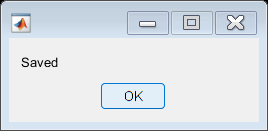

% Separar columna de fecha del pH y darle formato de fecha
phDate = datetime(phSplit(:,1), "InputFormat", "uuuu-MM-dd HH:mm:ss");

% Crear las líneas de caracteres para el Sami Client (sin asteriscos)
phArray = str2double(phSplit);
phCode = array2table(char(phArray(1:end,4:end)));
phCode(:, end-1:end) = [];

% Crear columna de asteriscos
astVar = num2str(zeros(numel(phCode.Var1), 1));
astVar(:, 1) = "*";

%Colocar dos columnas de asteriscos al principio y al final 
phCode.Ast1 = astVar;
phCode.Ast2 = astVar;
phCode = movevars(phCode, 'Ast1', 'Before', 1);
phCode = movevars(phCode, 'Ast2', 'After', width(phCode));

% Crear las líneas de caracteres para el Sami Client (con asteriscos)
phCode = table2array(phCode);

% Guardar en archivo client.txt

pHask = "Save SAMI lines in client.txt? y/n: ";

pHanswer = input(pHask, "s");

if pHanswer == "y"

    writematrix(phCode, 'C:\Users\usuario\Desktop\Datos_Boya_Gando\client.txt', 'Delimiter', 'space');
    msgbox("Saved")

end

## Importar archivo de pH (tras SAMI Client)

askName = "Name of pH file? (without extension): ";
nameFile = input(askName, "s");
phImp = importPH(['C:\Users\TESTER\OneDrive\Escritorio\Archivos y datos boyas\',nameFile,'.txt']);
 
disp('pH imported')

pH imported



% Crear tabla del pH para representar
phDef = table(phDate, phImp.TemperatureC, phImp.pHConstSal, phImp.DateStr, phImp.TimeStr, 'VariableNames', ["Date", "Temp", "pH", "Date2", "Time2"]);

## Representar

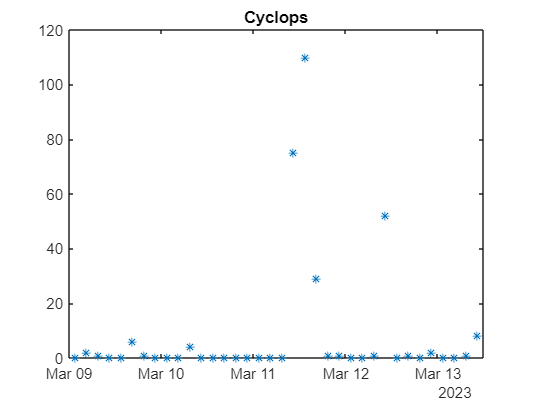

plot(cyc.Date, cyc.Value, "*")
title("Cyclops")

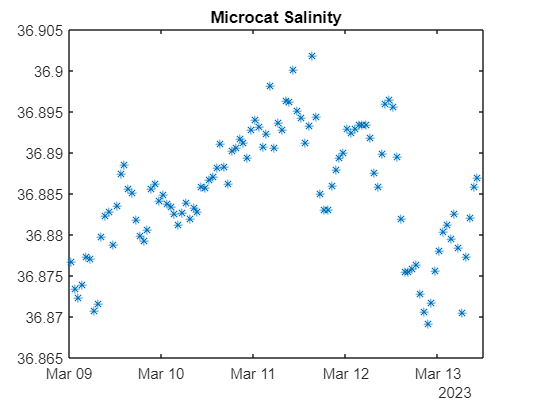


plot(sb.Date, sb.Salinity, "*")
title("Microcat Salinity")

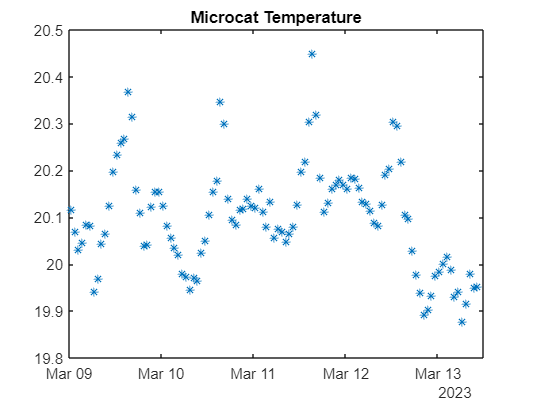

%ylim([36.8, 36.9])

plot(sb.Date, sb.Temperature, "*")
title("Microcat Temperature")

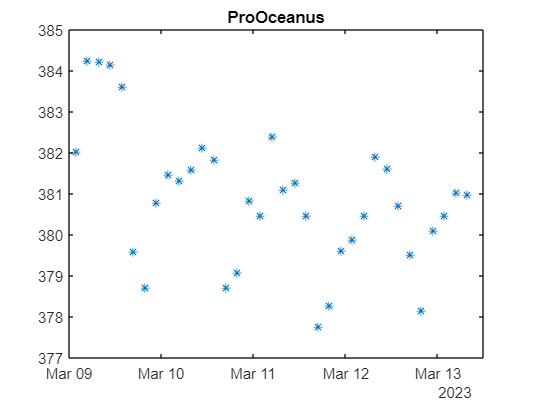


plot(co.Date, co.pCO2, "*")
title("ProOceanus")

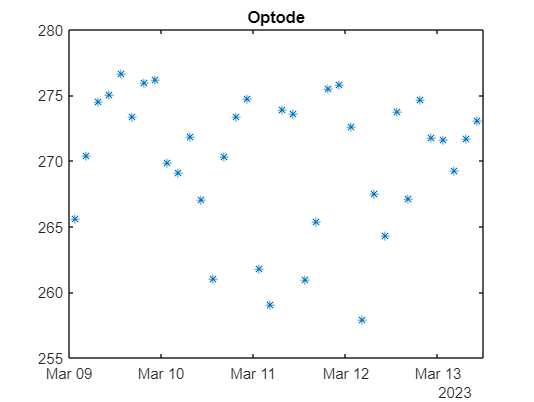


plot(rawOptode.Date, rawOptode.O2, "*")
title("Optode")


plot(phDef.Date, phDef.pH, "*")

Unable to resolve the name 'phDef.Date'.

title("SamiPH")
%ylim([8, 8.2])